# КУМС ЛР №1

Денис Кирбаба, R3438

%Tu = 0.03 + 0.02*(rand() - 0.5);
%save('data.mat', 'Tu')

## 1. Линейный оптимум

load('data.mat')
syms Tm s

Передаточная функция разомкнутой системы (e -> y)

Wol = 1/(Tm*s);

Передаточная функция замкнутой системы (g -> y)

Wcl = Wol / (1+Wol);
disp(collect(Wcl, s))

$$\frac{1}{\mathrm{Tm}\,s+1}$$

#### Переходный процесс

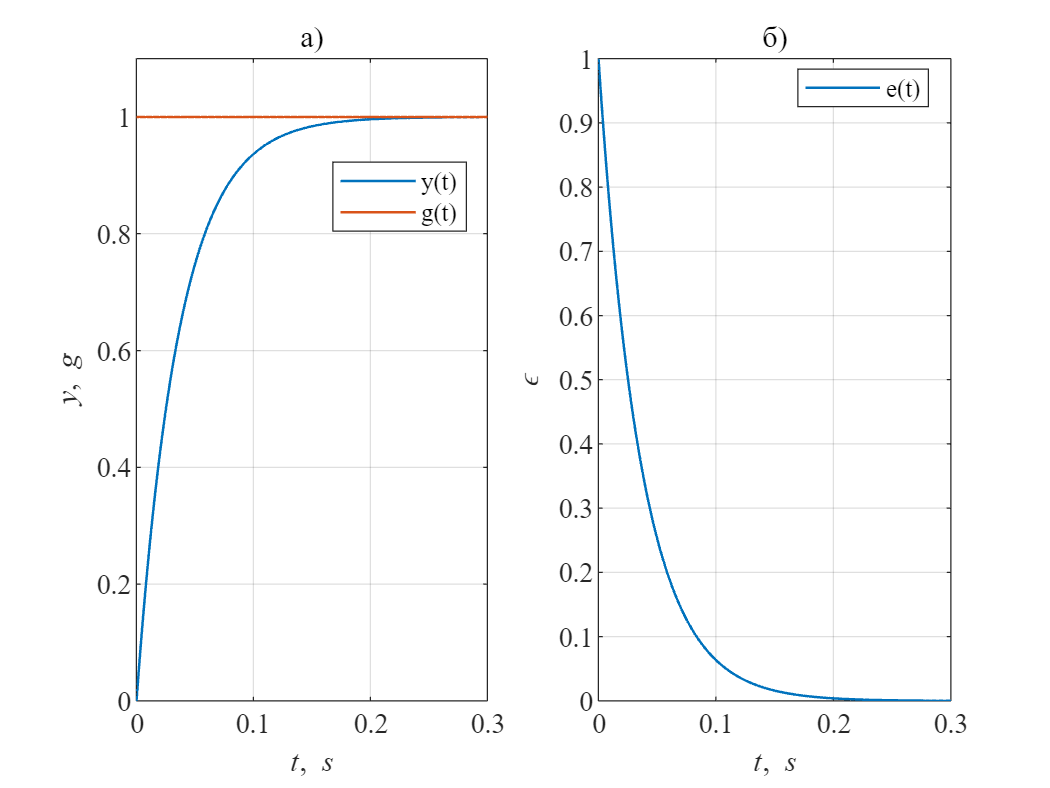

Tmdl = 0.3;
k = 1;

num = 1;
den = [Tu 0];

warning off
SimNew = sim("model.slx",'ReturnWorkspaceOutputs', 'on');
warning on

lim = 1;
trresp

Рисунок 1.1. Графики переходного процесса (а) и ошибки (б) при постоянном задающем воздействии.

#### Время переходного процесса (5% зона)

t0 = t(1);
y0 = y(1);
yss = y(end);
D5 = 0.05*abs(yss-y0);
ind = abs(y-yss) >= D5;
tn = t(ind);
ttr5 = tn(end)-t0;
fprintf('Время переходного процесса для 5%% зоны: %.3f*Tu \n',ttr5/Tu)

Время переходного процесса для 5% зоны: 2.965*Tu 


#### Время переходного процесса (2% зона)

t0 = t(1);
y0 = y(1);
yss = y(end);
D2 = 0.02*abs(yss-y0);
ind = abs(y-yss) >= D2;
tn = t(ind);
ttr2 = tn(end)-t0;
fprintf('Время переходного процесса для 2%% зоны: %.3f*Tu \n',ttr2/Tu)

Время переходного процесса для 2% зоны: 3.874*Tu 


#### Перерегулирование

dy = abs(max((y-yss)*sign(yss-y0))/(yss-y0));
fprintf('Перерегулирование: %.3f%% \n',dy*100)

Перерегулирование: 0.000% 


#### Линейно возрастающее воздействие

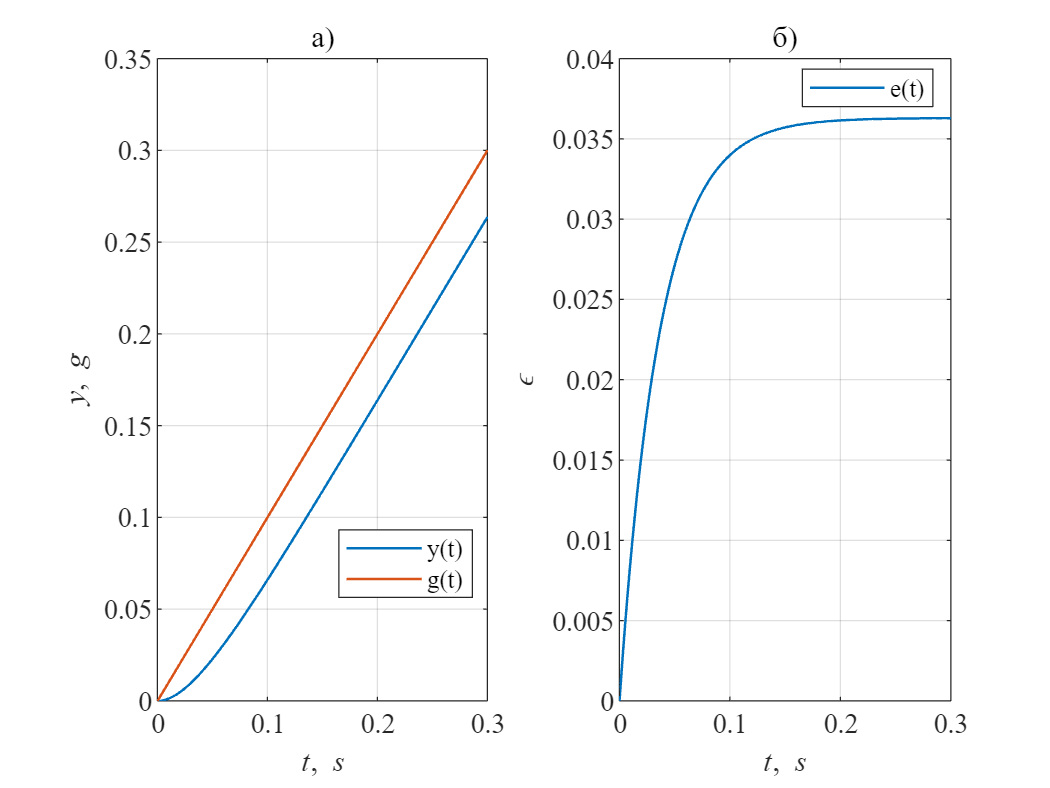

Tmdl = 0.3;
k = 2;

warning off
SimNew = sim("model.slx",'ReturnWorkspaceOutputs', 'on');
warning on

lim = 0;
trresp

Рисунок 1.2. Графики переходного процесса (а) и ошибки (б) при линейном задающем воздействии.

#### Квадратичное воздействие

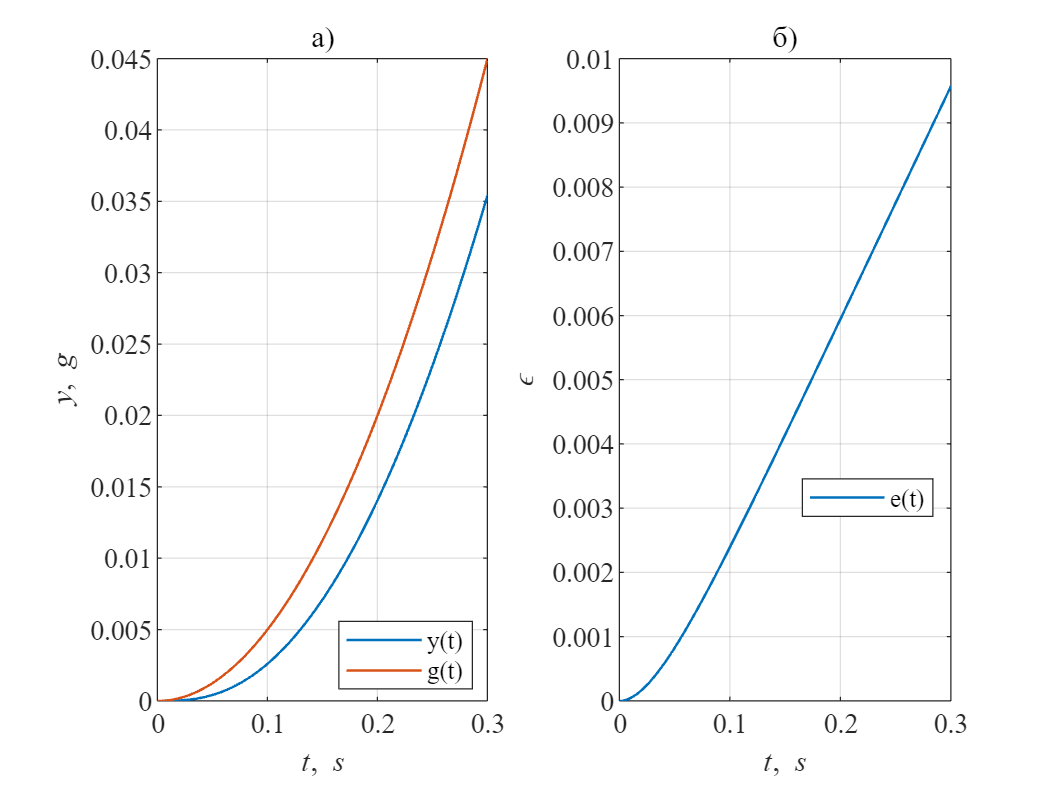

Tmdl = 0.3;
k = 3;

warning off
SimNew = sim("model.slx",'ReturnWorkspaceOutputs', 'on');
warning on

lim = 0;
trresp

Рисунок 1.3. Графики переходного процесса (а) и ошибки (б) при квадратичном задающем воздействии.

#### Запасы по амплитуде и по фазе

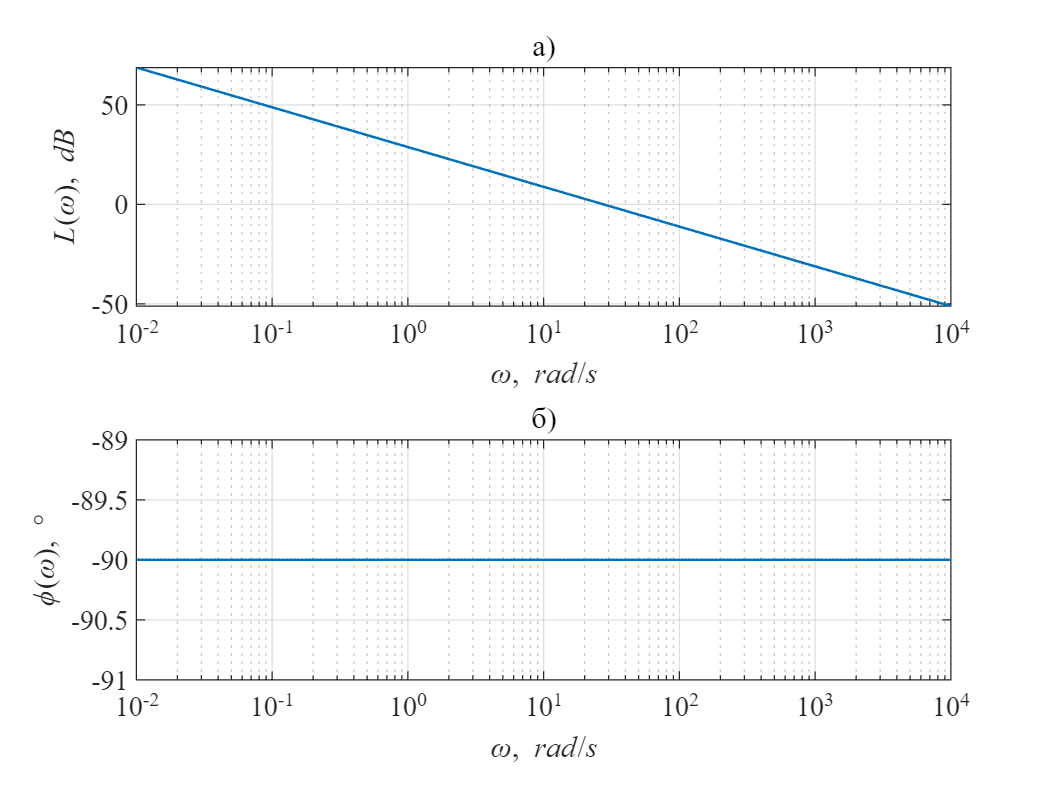

w = 10.^(-2:0.01:4);
sw = 1i*w;

Wol = 1./(Tu*sw);

[L, phi] = freqplot(w,Wol);

Рисунок 1.4. Графики ЛАЧХ (а) и ФЧХ (б) ПФ разомкнутой системы.

[Lmin, ind] = min(abs(L));
phi_marg = phi(ind) - (-180);
fprintf('Запас по фазе: %.3f%c при частоте %.3f рад/c\n',phi_marg,char(176),w(ind))

Запас по фазе: 90.000° при частоте 27.542 рад/c


tau_marg = phi_marg*pi/180/w(ind);
fprintf('Критическое запаздывание: %.3f мc\n',tau_marg*1000)

Критическое запаздывание: 57.032 мc


Запас по амплитуде равен бесконечности.

#### Показатель колебательности

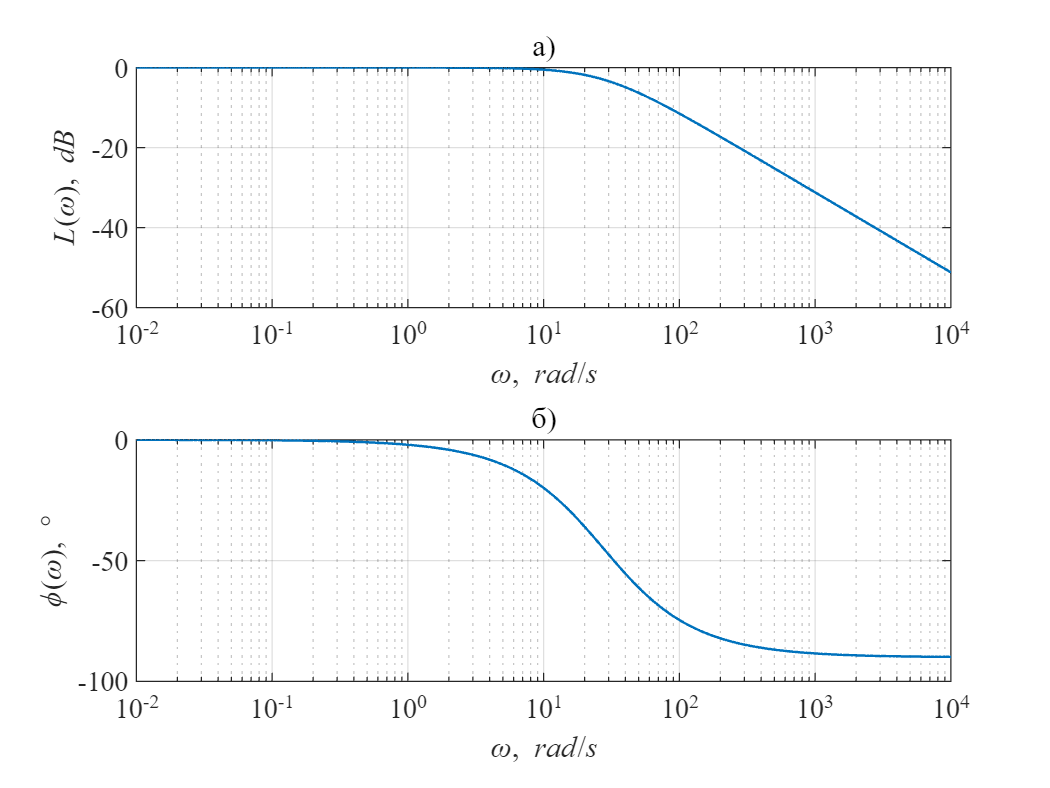

Wcl = Wol./(1 + Wol);

[L,phi] = freqplot(w,Wcl);

Рисунок 1.5. Графики АЧХ (а) и ФЧХ (б) ПФ замкнутой системы.

Показатель колебательности

M = 10^((max(L)-L(1))/20)/10^(L(1)/20);
fprintf('Показатель колебательности M: %.3f \n',M)

Показатель колебательности M: 1.000 


## 2. Биномиальный оптимум

load('data.mat')
syms Tm s

Передаточная функция разомкнутой системы (e -> y)

Wol = 1/(3*Tm*s*(Tm*s + 1));

Передаточная функция замкнутой системы (g -> y)

Wcl = Wol / (1+Wol);
disp(collect(Wcl, s))

$$\frac{1}{\left(3\,{\mathrm{Tm}}^{2}\right)\,s^{2}+\left(3\,\mathrm{Tm}\right)\,s+1}$$

#### Переходный процесс

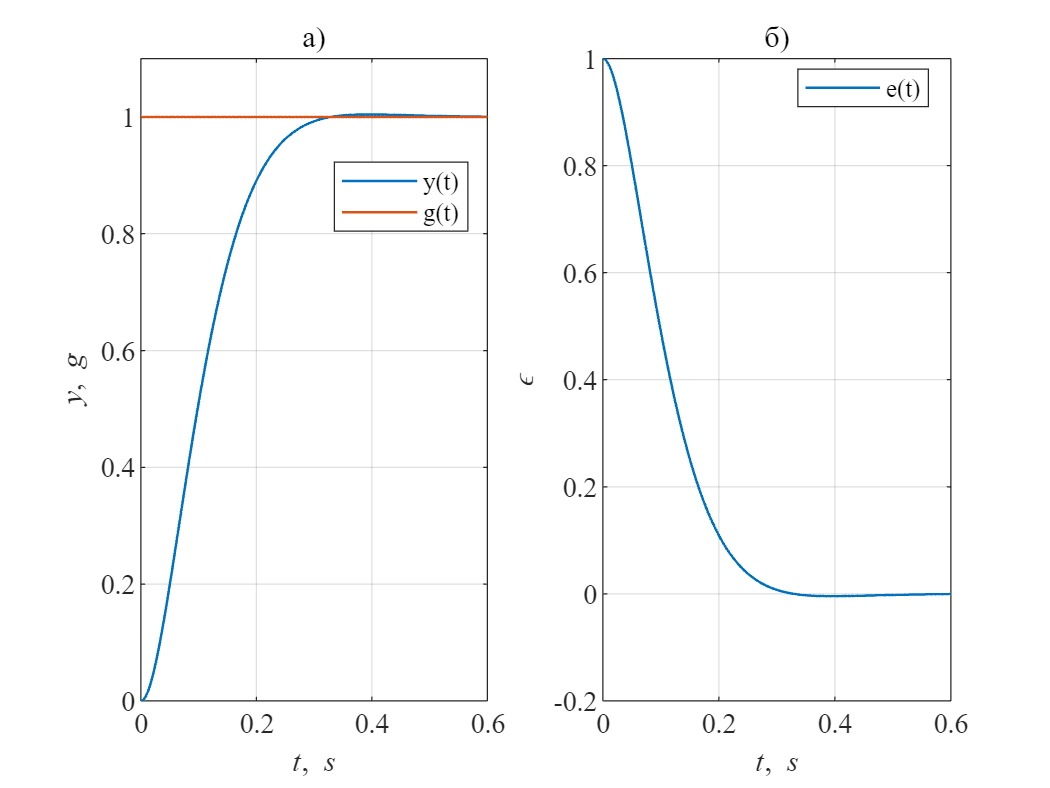

Tmdl = 0.6;
k = 1;

num = 1;
den = [3*Tu^2 3*Tu 0];

warning off
SimNew = sim("model.slx",'ReturnWorkspaceOutputs', 'on');
warning on

lim = 1;
trresp

Рисунок 2.1. Графики переходного процесса (а) и ошибки (б) при постоянном задающем воздействии.

#### Время переходного процесса (5% зона)

t0 = t(1);
y0 = y(1);
yss = y(end);
D5 = 0.05*abs(yss-y0);
ind = abs(y-yss) >= D5;
tn = t(ind);
ttr5 = tn(end)-t0;
fprintf('Время переходного процесса для 5%% зоны: %.3f*Tu \n',ttr5/Tu)

Время переходного процесса для 5% зоны: 6.546*Tu 


#### Время переходного процесса (2% зона)

t0 = t(1);
y0 = y(1);
yss = y(end);
D2 = 0.02*abs(yss-y0);
ind = abs(y-yss) >= D2;
tn = t(ind);
ttr2 = tn(end)-t0;
fprintf('Время переходного процесса для 2%% зоны: %.3f*Tu \n',ttr2/Tu)

Время переходного процесса для 5% зоны: 7.538*Tu 


#### Перерегулирование

dy = abs(max((y-yss)*sign(yss-y0))/(yss-y0));
fprintf('Перерегулирование: %.3f%% \n',dy*100)

Перерегулирование: 0.390% 


#### Линейно возрастающее воздействие

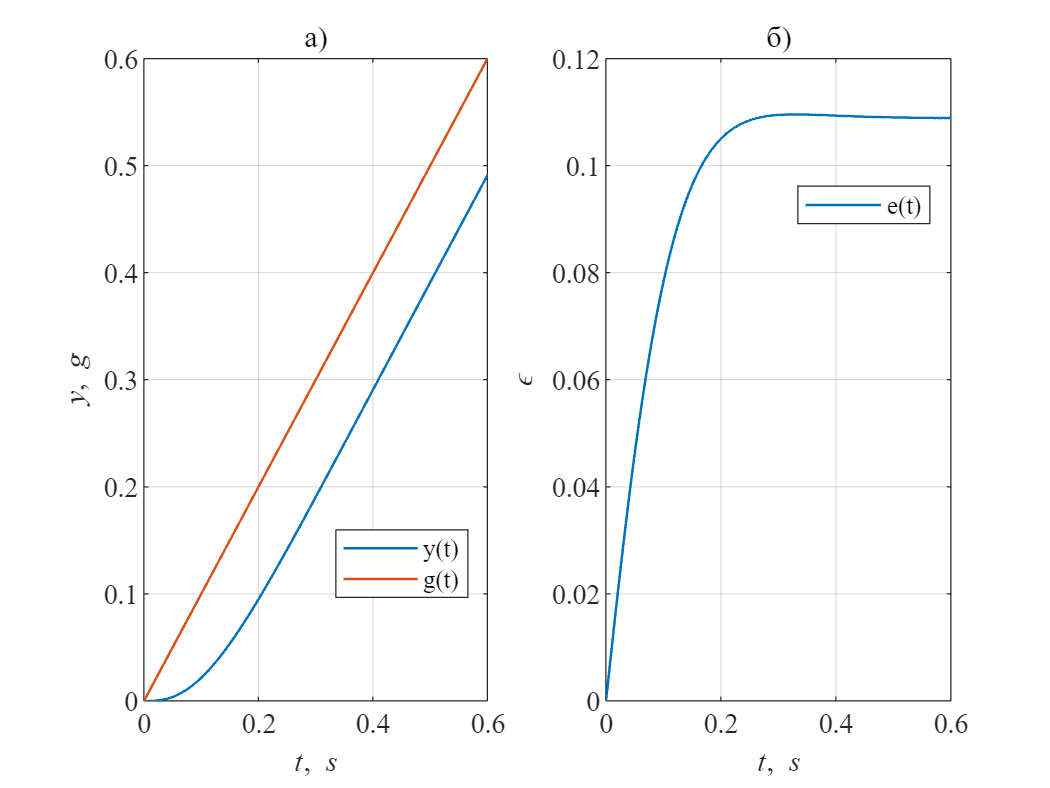

Tmdl = 0.6;
k = 2;

warning off
SimNew = sim("model.slx",'ReturnWorkspaceOutputs', 'on');
warning on

lim = 0;
trresp

Рисунок 2.2. Графики переходного процесса (а) и ошибки (б) при линейном задающем воздействии.

#### Квадратичное воздействие

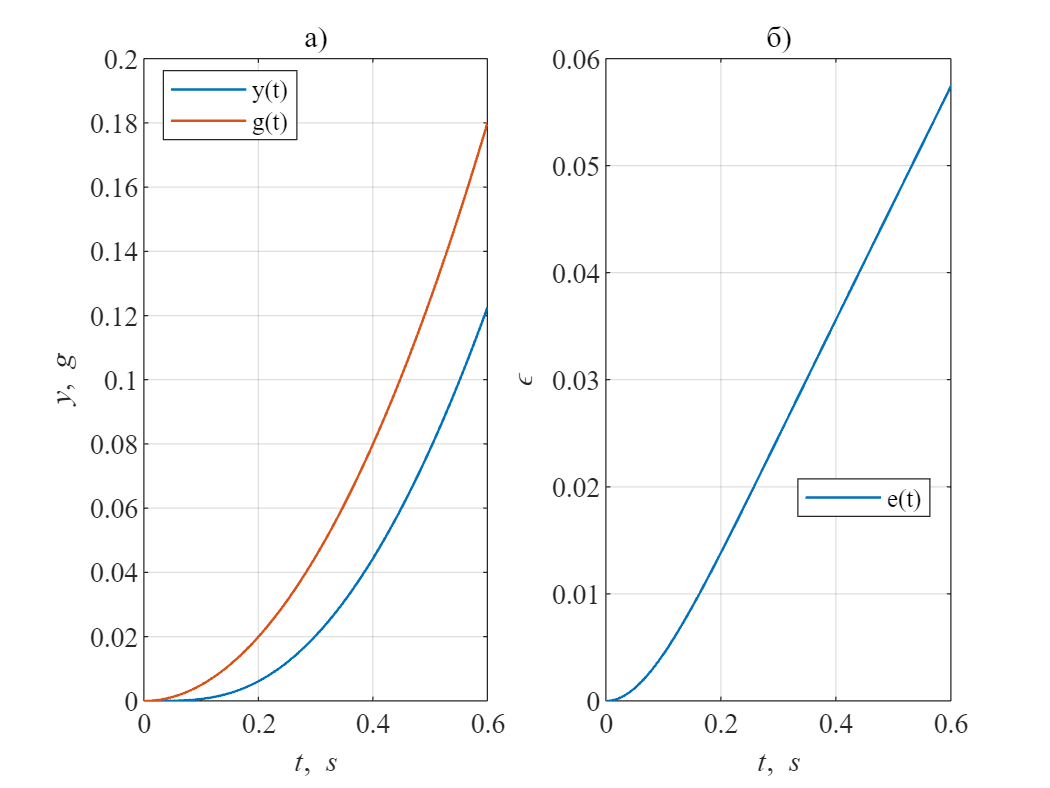

Tmdl = 0.6;
k = 3;

warning off
SimNew = sim("model.slx",'ReturnWorkspaceOutputs', 'on');
warning on

lim = 0;
trresp

Рисунок 2.3. Графики переходного процесса (а) и ошибки (б) при квадратичном задающем воздействии.

#### Запасы по амплитуде и по фазе

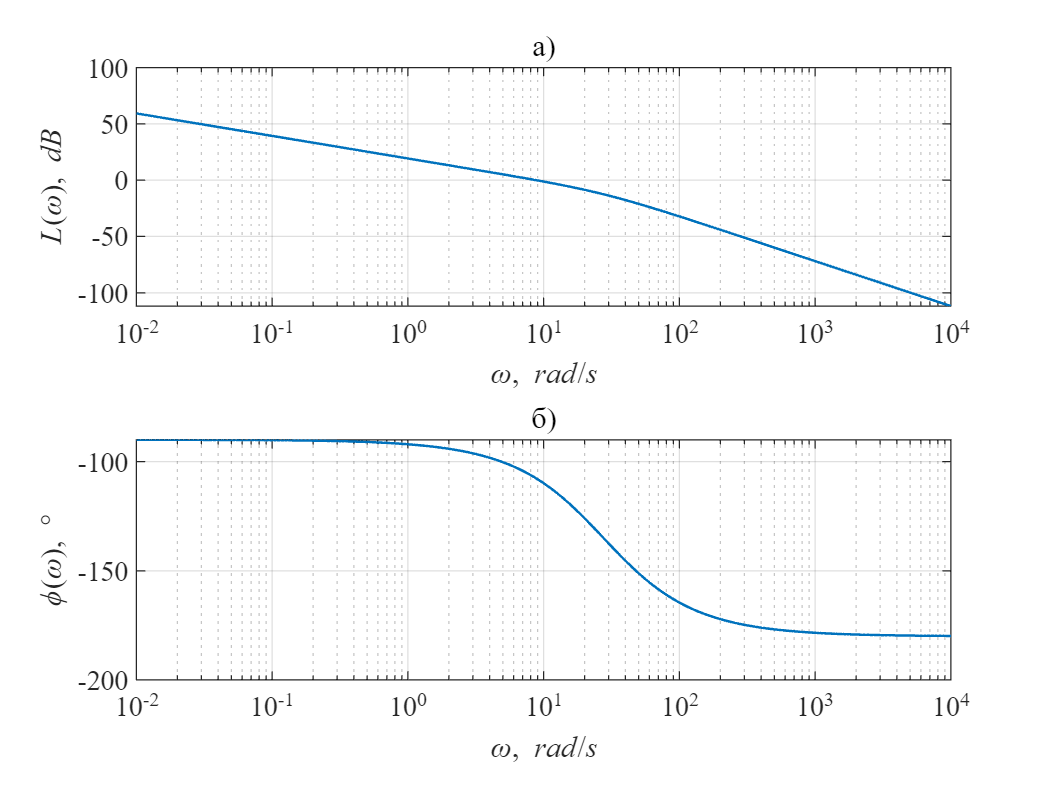

w = 10.^(-2:0.01:4);
sw = 1i*w;

Wol = 1./(3*Tu*sw.*(Tu*sw+1));

[L, phi] = freqplot(w,Wol);

Рисунок 2.4. Графики АЧХ (а) и ФЧХ (б) ПФ разомкнутой системы.

Запас по фазе

[Lmin, ind] = min(abs(L));
phi_marg = phi(ind) - (-180);
fprintf('Запас по фазе: %.3f%c при частоте %.3f рад/c\n',phi_marg,char(176),w(ind))

Запас по фазе: 72.458° при частоте 8.710 рад/c


tau_marg = phi_marg*pi/180/w(ind);
fprintf('Критическое запаздывание: %.3f мc\n',tau_marg*1000)

Критическое запаздывание: 145.198 мc


[Gm,Pm,Wcg,Wcp] = margin(tf(num,den))

Gm = Inf

Pm = 72.3756

Wcg = Inf

Wcp = 8.7530

Запас по амплитуде равен бесконечности

#### Показатель колебательности

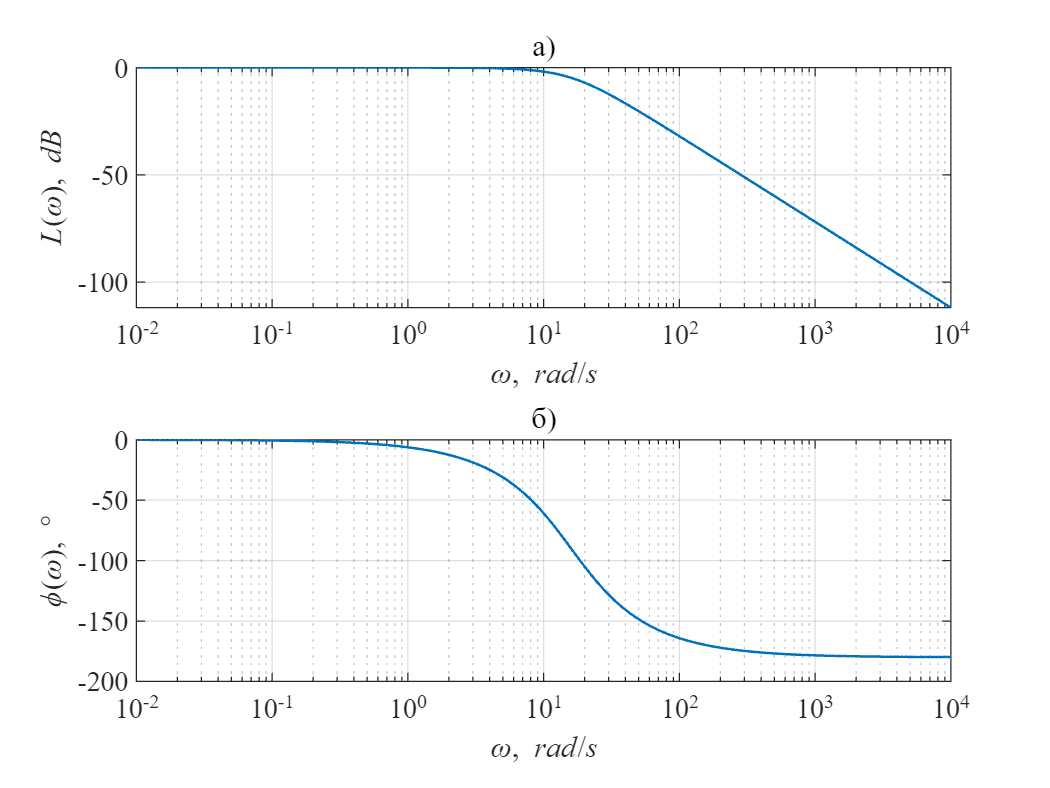

Wcl = Wol./(1 + Wol);

[L,phi] = freqplot(w,Wcl);

Рисунок 2.5. Графики АЧХ (а) и ФЧХ (б) ПФ замкнутой системы.

M = 10^((max(L)-L(1))/20)/10^(L(1)/20);
fprintf('Показатель колебательности M: %.3f \n',M)

Показатель колебательности M: 1.000 


## 3. Технический оптимум

load('data.mat')
syms Tm s

Передаточная функция разомкнутой системы (e -> y)

Wol = 1/(2*Tm*s*(Tm*s + 1));

Передаточная функция замкнутой системы (g -> y)

Wcl = Wol / (1+Wol);
disp(collect(Wcl, s))

$$\frac{1}{\left(2\,{\mathrm{Tm}}^{2}\right)\,s^{2}+\left(2\,\mathrm{Tm}\right)\,s+1}$$

#### Переходный процесс

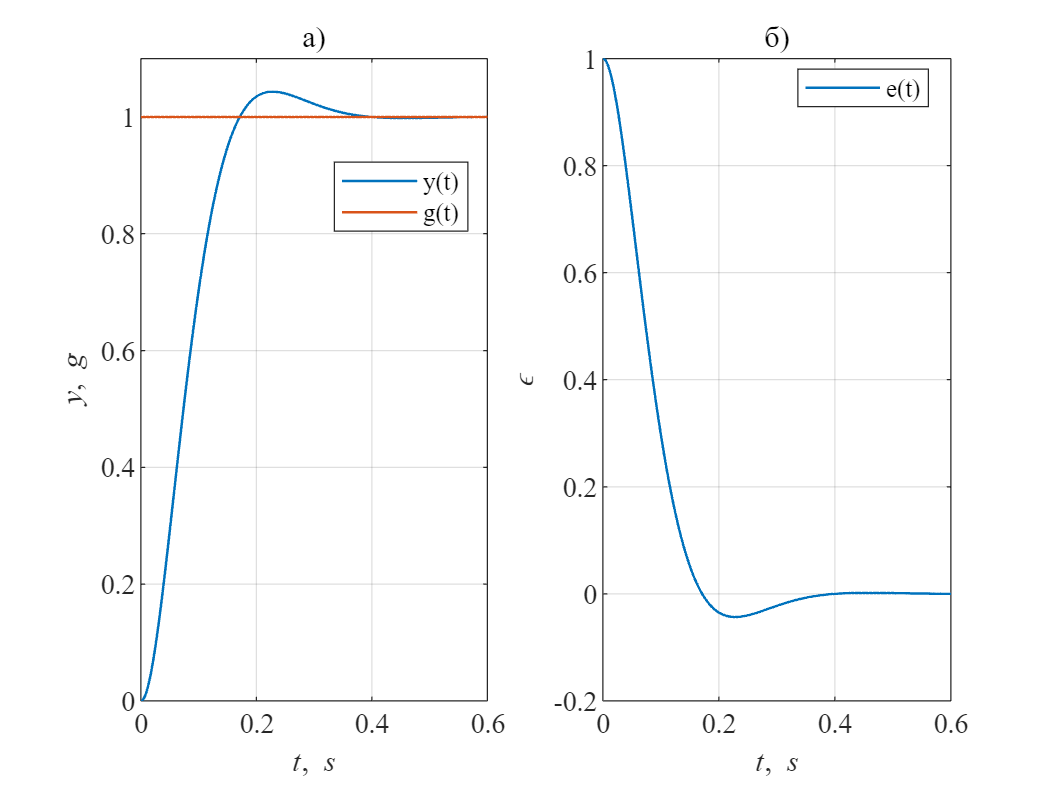

Tmdl = 0.6;
k = 1;

num = 1;
den = [2*Tu^2 2*Tu 0];

warning off
SimNew = sim("model.slx",'ReturnWorkspaceOutputs', 'on');
warning on

lim = 1;
trresp

Рисунок 3.1. Графики переходного процесса (а) и ошибки (б) при постоянном задающем воздействии.

#### Время переходного процесса (5% зона)

t0 = t(1);
y0 = y(1);
yss = y(end);
D5 = 0.05*abs(yss-y0);
ind = abs(y-yss) >= D5;
tn = t(ind);
ttr5 = tn(end)-t0;
fprintf('Время переходного процесса для 5%% зоны: %.3f*Tu \n',ttr5/Tu)

Время переходного процесса для 5% зоны: 4.122*Tu 


#### Время переходного процесса (2% зона)

t0 = t(1);
y0 = y(1);
yss = y(end);
D2 = 0.02*abs(yss-y0);
ind = abs(y-yss) >= D2;
tn = t(ind);
ttr2 = tn(end)-t0;
fprintf('Время переходного процесса для 2%% зоны: %.3f*Tu \n',ttr2/Tu)

Время переходного процесса для 2% зоны: 8.420*Tu 


#### Перерегулирование

dy = abs(max((y-yss)*sign(yss-y0))/(yss-y0));
fprintf('Перерегулирование: %.3f%% \n',dy*100)

Перерегулирование: 4.335% 


#### Линейно возрастающее воздействие

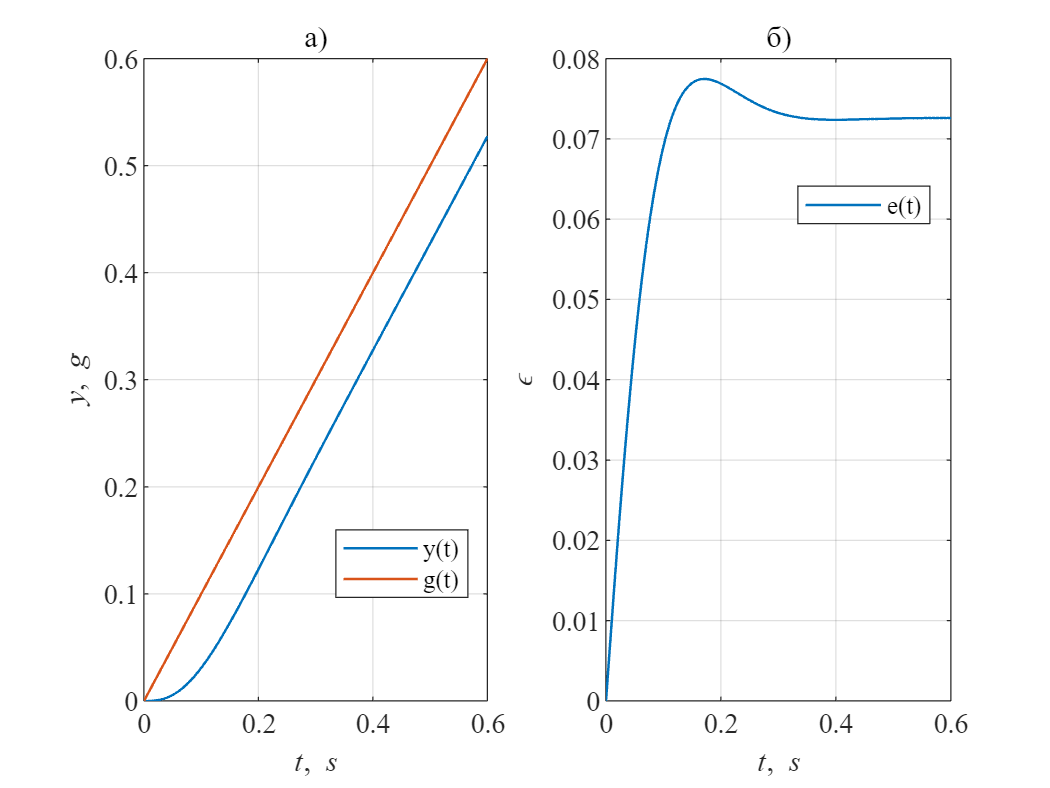

Tmdl = 0.6;
k = 2;

warning off
SimNew = sim("model.slx",'ReturnWorkspaceOutputs', 'on');
warning on

lim = 0;
trresp

Рисунок 3.2. Графики переходного процесса (а) и ошибки (б) при линейном задающем воздействии.

#### Квадратичное воздействие

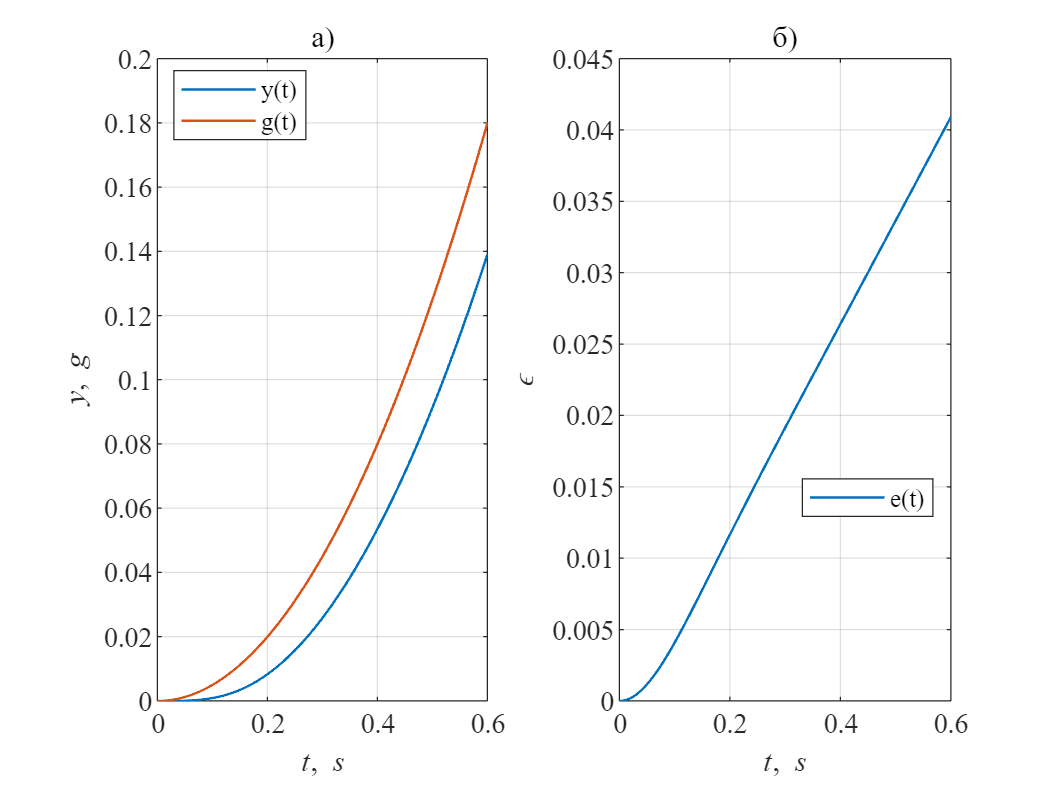

Tmdl = 0.6;
k = 3;

warning off
SimNew = sim("model.slx",'ReturnWorkspaceOutputs', 'on');
warning on

lim = 0;
trresp

Рисунок 3.3. Графики переходного процесса (а) и ошибки (б) при квадратичном задающем воздействии.

#### Запасы по амплитуде и по фазе

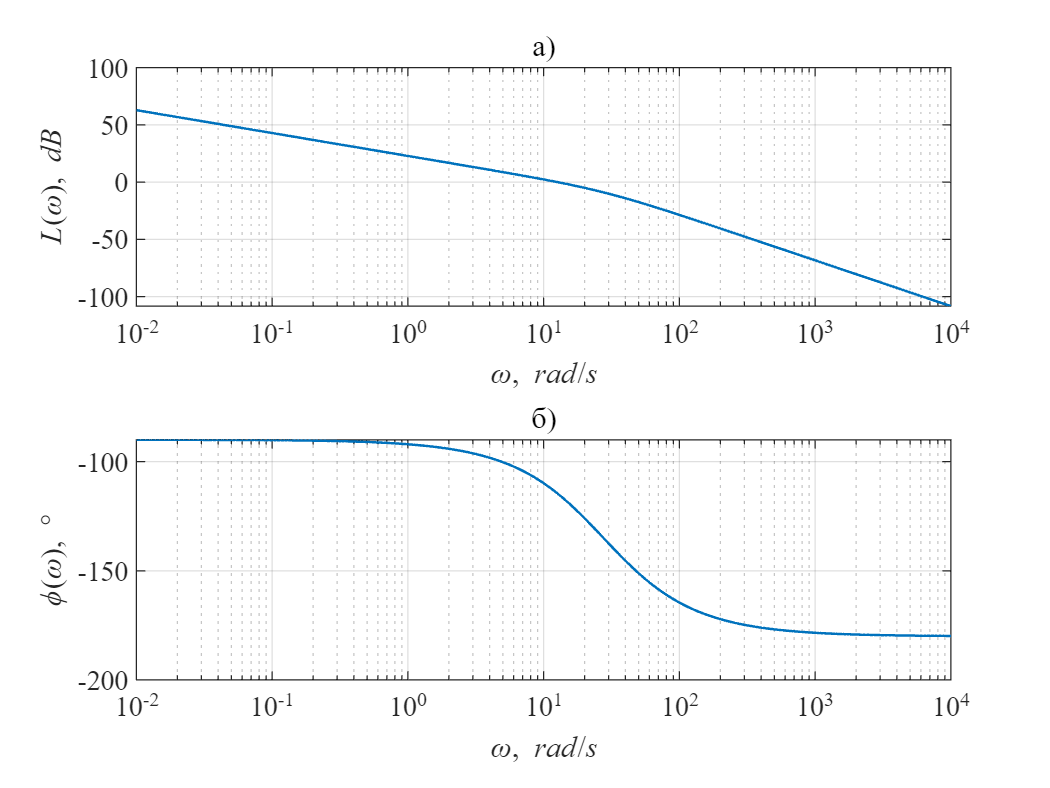

w = 10.^(-2:0.01:4);
sw = 1i*w;

Wol = 1./(2*Tu*sw.*(Tu*sw+1));

[L, phi] = freqplot(w,Wol);

Рисунок 3.4. Графики АЧХ (а) и ФЧХ (б) ПФ разомкнутой системы.

[Lmin, ind] = min(abs(L));
phi_marg = phi(ind) - (-180);
fprintf('Запас по фазе: %.3f%c при частоте %.3f рад/c\n',phi_marg,char(176),w(ind))

Запас по фазе: 65.443° при частоте 12.589 рад/c


tau_marg = phi_marg*pi/180/w(ind);
fprintf('Критическое запаздывание: %.3f мc\n',tau_marg*1000)

Критическое запаздывание: 90.728 мc


[Gm,Pm,Wcg,Wcp] = margin(tf(num,den))

Gm = Inf

Pm = 65.5302

Wcg = Inf

Wcp = 12.5388

Запас по амплитуде равен бесконечности

#### Показатель колебательности

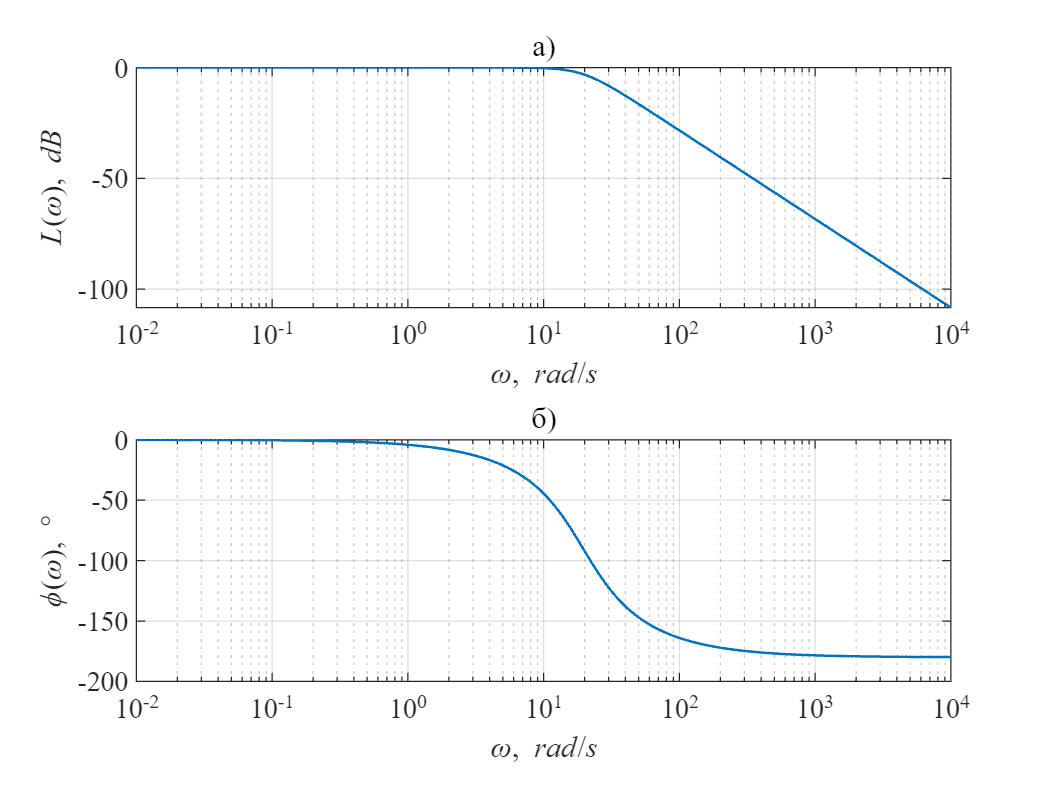

Wcl = Wol./(1 + Wol);

[L,phi] = freqplot(w,Wcl);

Рисунок 3.5. Графики АЧХ (а) и ФЧХ (б) ПФ замкнутой системы.

M = 10^((max(L)-L(1))/20)/10^(L(1)/20);
fprintf('Показатель колебательности M: %.3f \n',M)

Показатель колебательности M: 1.000 


## 4. Симметричный оптимум

load('data.mat')
syms Tm s

Передаточная функция разомкнутой системы (e -> y)

Wol = (4*Tm*s+1)/(8*Tm^2*s^2*(Tm*s + 1));

Передаточная функция замкнутой системы (g -> y)

Wcl = Wol / (1+Wol);
disp(collect(Wcl, s))

$$\frac{\left(4\,\mathrm{Tm}\right)\,s+1}{\left(8\,{\mathrm{Tm}}^{3}\right)\,s^{3}+\left(8\,{\mathrm{Tm}}^{2}\right)\,s^{2}+\left(4\,\mathrm{Tm}\right)\,s+1}$$

#### Переходный процесс

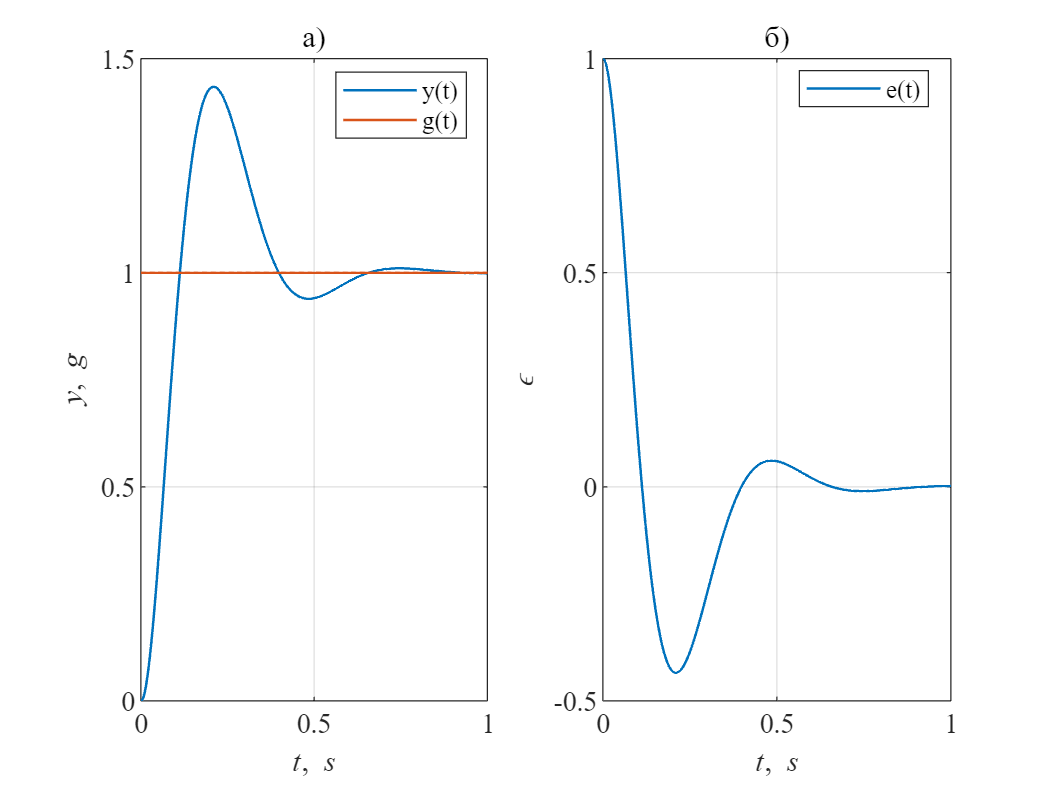

Tmdl = 1;
k = 1;

num = [4*Tu 1];
den = [8*Tu^3 8*Tu^2 0 0];

warning off
SimNew = sim("model.slx",'ReturnWorkspaceOutputs', 'on');
warning on

lim = 0;
trresp

Рисунок 4.1. Графики переходного процесса (а) и ошибки (б) при постоянном задающем воздействии.

#### Время переходного процесса (5% зона)

t0 = t(1);
y0 = y(1);
yss = y(end);
D5 = 0.05*abs(yss-y0);
ind = abs(y-yss) >= D5;
tn = t(ind);
ttr5 = tn(end)-t0;
fprintf('Время переходного процесса для 5%% зоны: %.3f*Tu \n',ttr5/Tu)

Время переходного процесса для 5% зоны: 14.564*Tu 


#### Время переходного процесса (2% зона)

t0 = t(1);
y0 = y(1);
yss = y(end);
D2 = 0.02*abs(yss-y0);
ind = abs(y-yss) >= D2;
tn = t(ind);
ttr2 = tn(end)-t0;
fprintf('Время переходного процесса для 2%% зоны: %.3f*Tu \n',ttr2/Tu)

Время переходного процесса для 2% зоны: 16.438*Tu 


#### Перерегулирование

dy = abs(max((y-yss)*sign(yss-y0))/(yss-y0));
fprintf('Перерегулирование: %.3f%% \n',dy*100)

Перерегулирование: 43.647% 


#### Линейно возрастающее воздействие

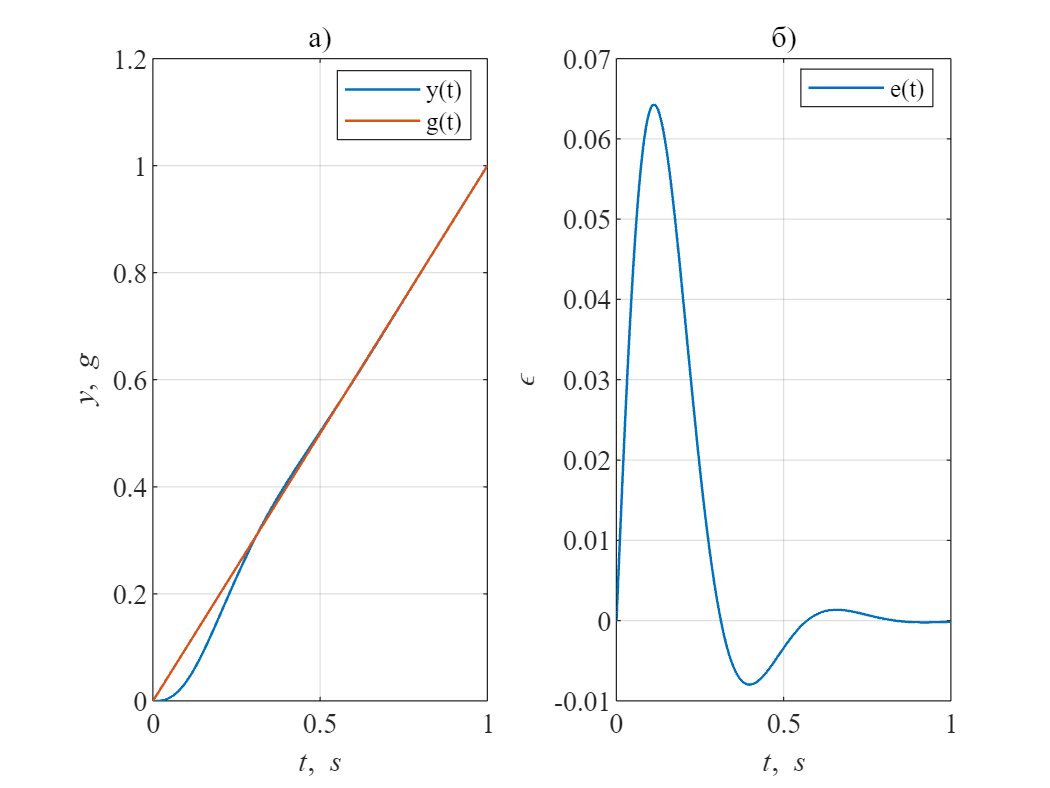

Tmdl = 1;
k = 2;

warning off
SimNew = sim("model.slx",'ReturnWorkspaceOutputs', 'on');
warning on

lim = 0;
trresp

Рисунок 4.2. Графики переходного процесса (а) и ошибки (б) при линейном задающем воздействии.

#### Квадратичное воздействие

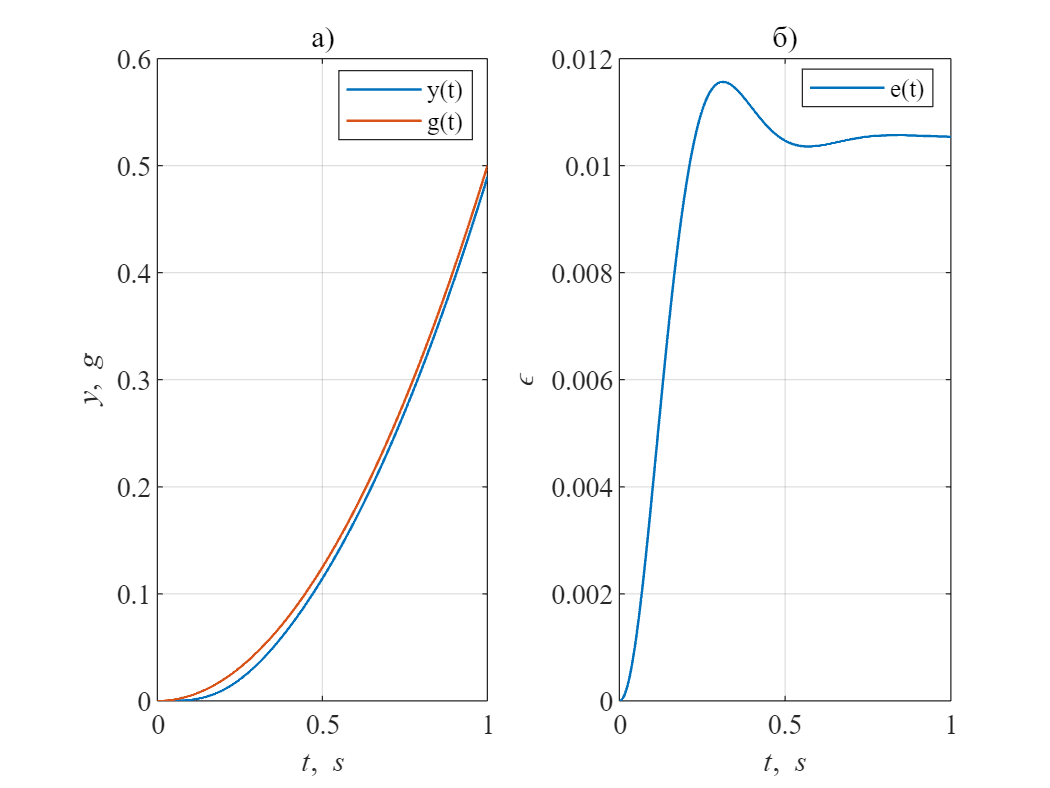

Tmdl = 1;
k = 3;

warning off
SimNew = sim("model.slx",'ReturnWorkspaceOutputs', 'on');
warning on

lim = 0;
trresp

Рисунок 4.3. Графики переходного процесса (а) и ошибки (б) при квадратичном задающем воздействии.

#### Запасы по амплитуде и по фазе

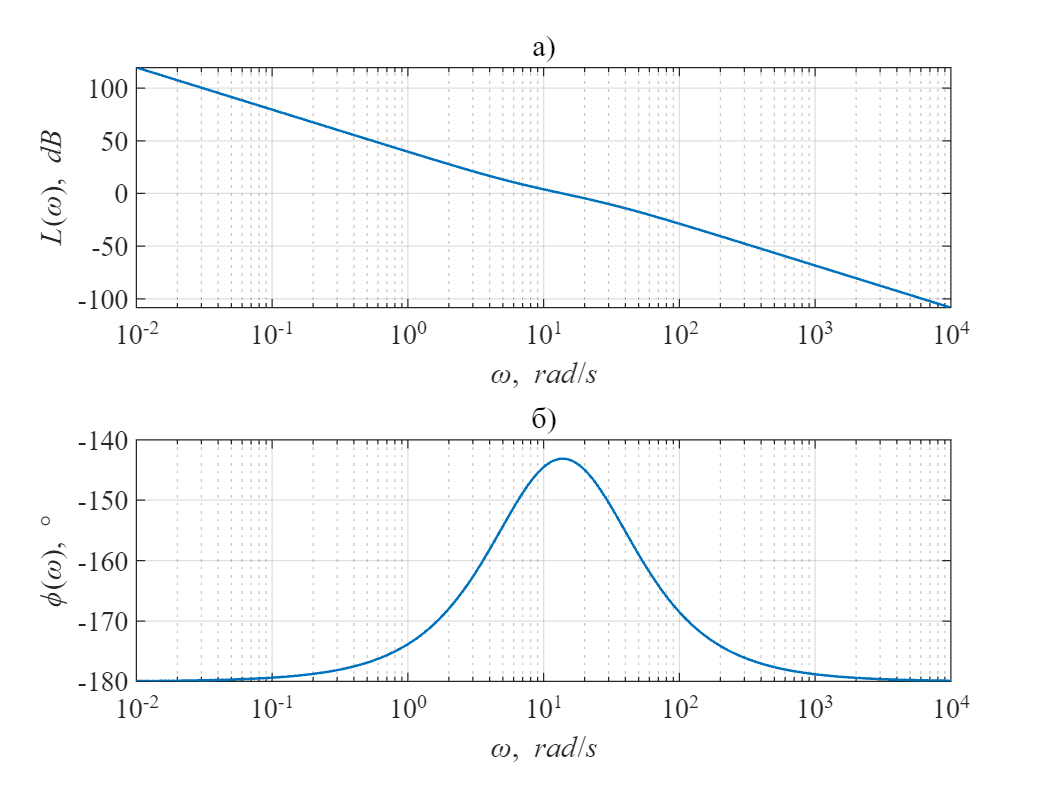

w = 10.^(-2:0.01:4);
sw = 1i*w;

Wol = (4*Tu*sw + 1)./(8*Tu^2*sw.^2.*(Tu*sw+1));

[L, phi] = freqplot(w,Wol);

Рисунок 4.4. Графики АЧХ (а) и ФЧХ (б) ПФ разомкнутой системы.

[Lmin, ind] = min(abs(L));
phi_marg = phi(ind) - (-180);
fprintf('запас по фазе: %.3f%c при частоте %.3f рад/c\n',phi_marg,char(176),w(ind))

запас по фазе: 36.870° при частоте 13.804 рад/c


tau_marg = phi_marg*pi/180/w(ind);
fprintf('критическое запаздывание: %.3f мc\n',tau_marg*1000)

критическое запаздывание: 46.617 мc


[Gm,Pm,Wcg,Wcp] = margin(tf(num,den))

Gm = 0

Pm = 36.8699

Wcg = 0

Wcp = 13.7762

Запас по амплитуде равен бесконечности

#### Показатель колебательности

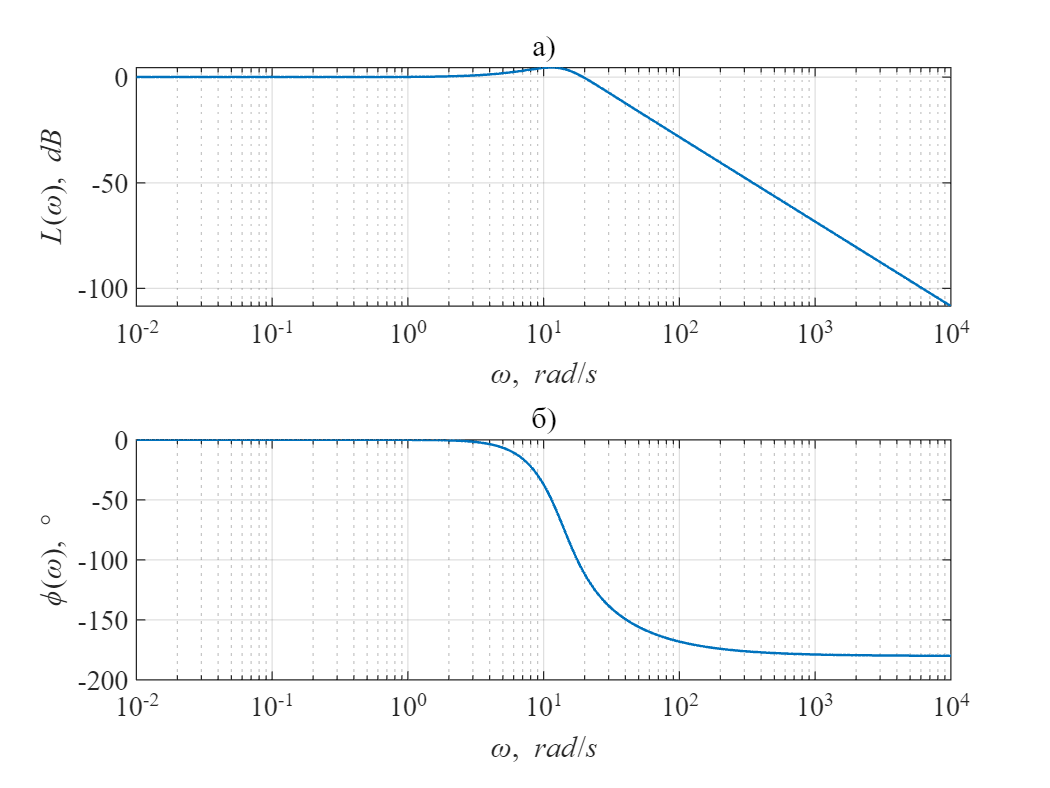

Wcl = Wol./(1 + Wol);

[L,phi] = freqplot(w,Wcl);

Рисунок 4.5. Графики АЧХ (а) и ФЧХ (б) ПФ замкнутой системы.

M = 10^((max(L)-L(1))/20)/10^(L(1)/20);
fprintf('Показатель колебательности M: %.3f \n',M)

Показатель колебательности M: 1.682 


## 5. Система, настроенная на астатизм 3-го порядка

load('data.mat')
syms Tm s

Передаточная функция разомкнутой системы (e -> y)

Wol = (16*Tm*s+1)*(4*Tm*s + 1)/(128*Tm^3*s^3*(Tm*s + 1));

Передаточная функция замкнутой системы (g -> y)

Wcl = Wol / (1+Wol);
disp(collect(Wcl, s))

$$\frac{\left(64\,{\mathrm{Tm}}^{2}\right)\,s^{2}+\left(20\,\mathrm{Tm}\right)\,s+1}{\left(128\,{\mathrm{Tm}}^{4}\right)\,s^{4}+\left(128\,{\mathrm{Tm}}^{3}\right)\,s^{3}+\left(64\,{\mathrm{Tm}}^{2}\right)\,s^{2}+\left(20\,\mathrm{Tm}\right)\,s+1}$$

#### Переходный процесс

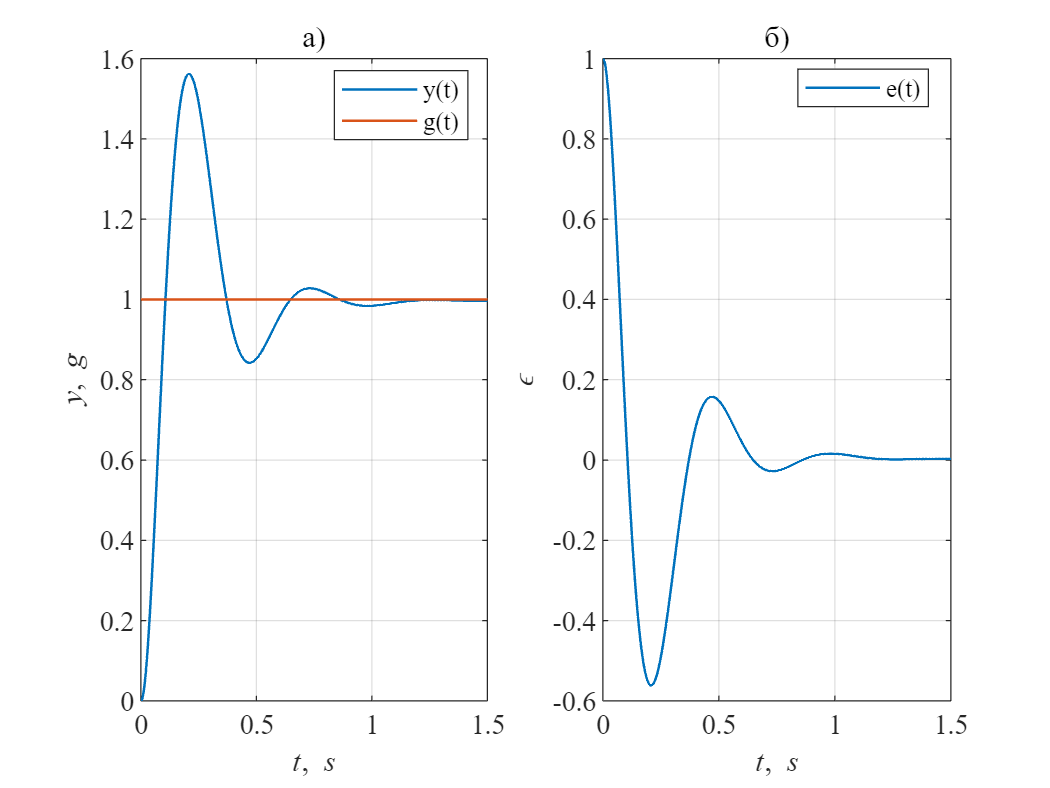

Tmdl = 1.5;
k = 1;

num = [64*Tu^2 20*Tu 1];
den = [128*Tu^4 128*Tu^3 0 0 0];

warning off
SimNew = sim("model.slx",'ReturnWorkspaceOutputs', 'on');
warning on

lim = 0;
trresp

Рисунок 5.1. Графики переходного процесса (а) и ошибки (б) при постоянном задающем воздействии.

#### Время переходного процесса (5% зона)

t0 = t(1);
y0 = y(1);
yss = y(end);
D5 = 0.05*abs(yss-y0);
ind = abs(y-yss) >= D5;
tn = t(ind);
ttr5 = tn(end)-t0;
fprintf('Время переходного процесса для 5%% зоны: %.3f*Tu \n',ttr5/Tu)

Время переходного процесса для 5% зоны: 16.2*Tu 


#### Время переходного процесса (2% зона)

t0 = t(1);
y0 = y(1);
yss = y(end);
D2 = 0.02*abs(yss-y0);
ind = abs(y-yss) >= D2;
tn = t(ind);
ttr2 = tn(end)-t0;
fprintf('Время переходного процесса для 2%% зоны: %.3f*Tu \n',ttr2/Tu)

Время переходного процесса для 2% зоны: 22.0*Tu 


#### Перерегулирование

dy = abs(max((y-yss)*sign(yss-y0))/(yss-y0));
fprintf('Перерегулирование: %.3f%% \n',dy*100)

Перерегулирование: 56.7% 


#### Линейно возрастающее воздействие

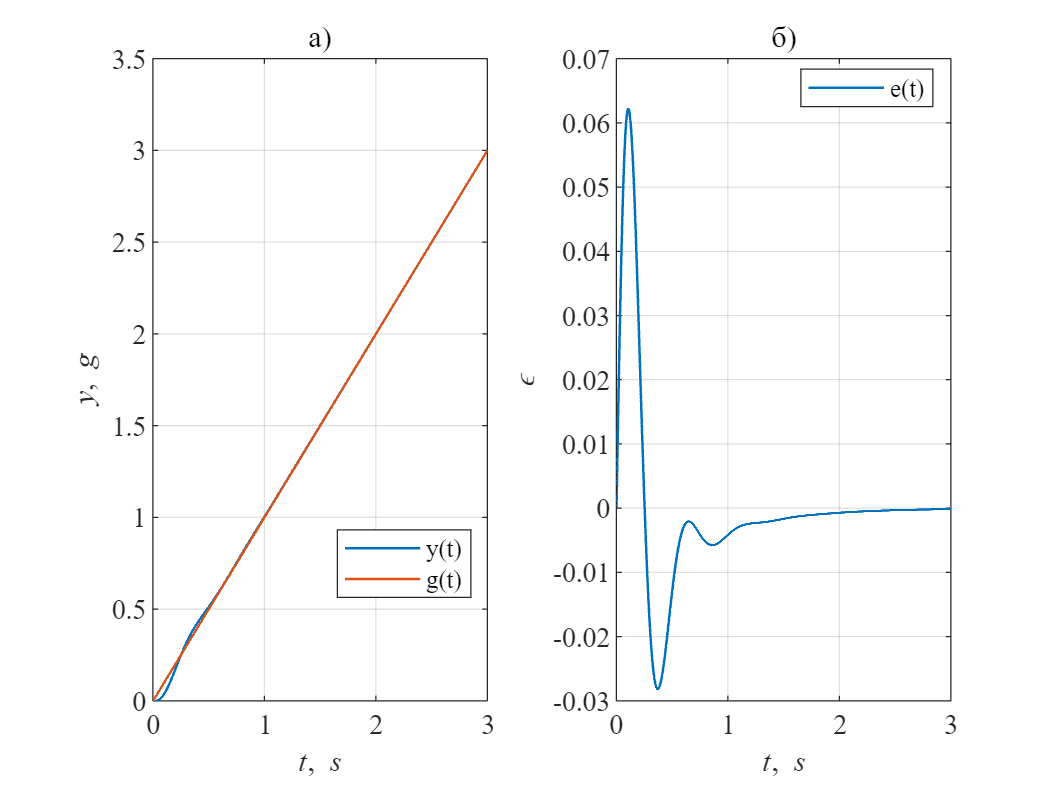

Tmdl = 3;
k = 2;

warning off
SimNew = sim("model.slx",'ReturnWorkspaceOutputs', 'on');
warning on

lim = 0;
trresp

Рисунок 5.2. Графики переходного процесса (а) и ошибки (б) при линейном задающем воздействии.

#### Квадратичное воздействие

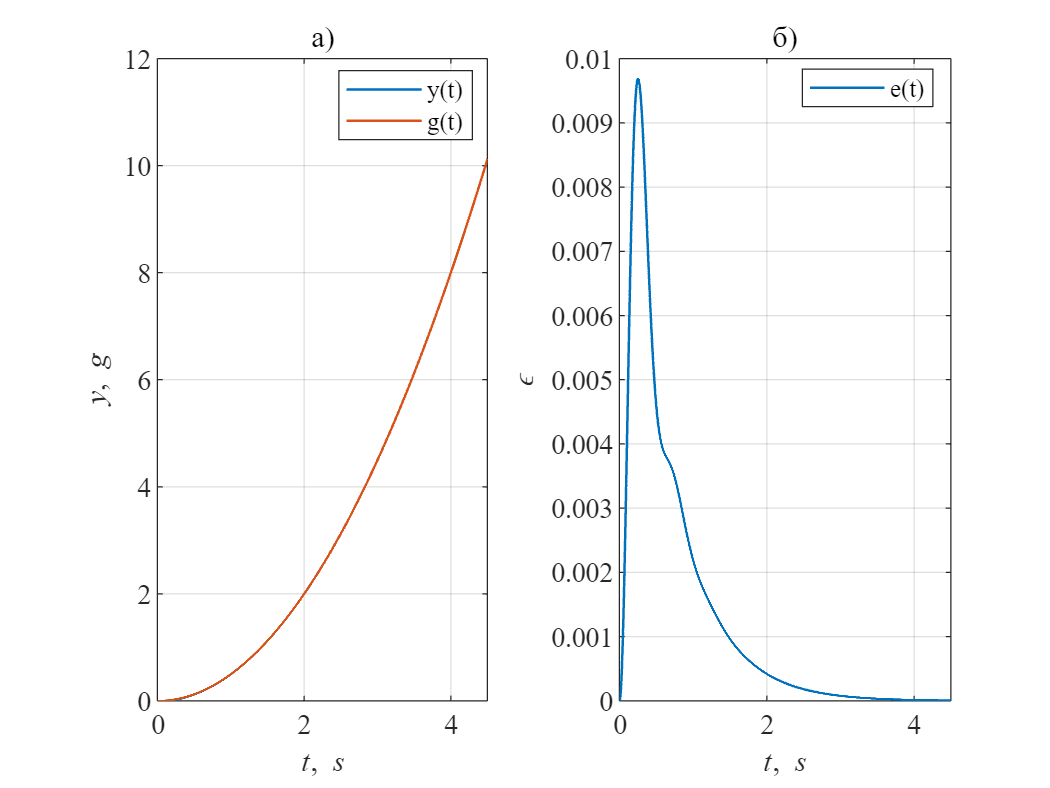

Tmdl = 4.5;
k = 3;

warning off
SimNew = sim("model.slx",'ReturnWorkspaceOutputs', 'on');
warning on

lim = 0;
trresp

Рисунок 5.3. Графики переходного процесса (а) и ошибки (б) при квадратичном задающем воздействии.

#### Запасы по амплитуде и по фазе

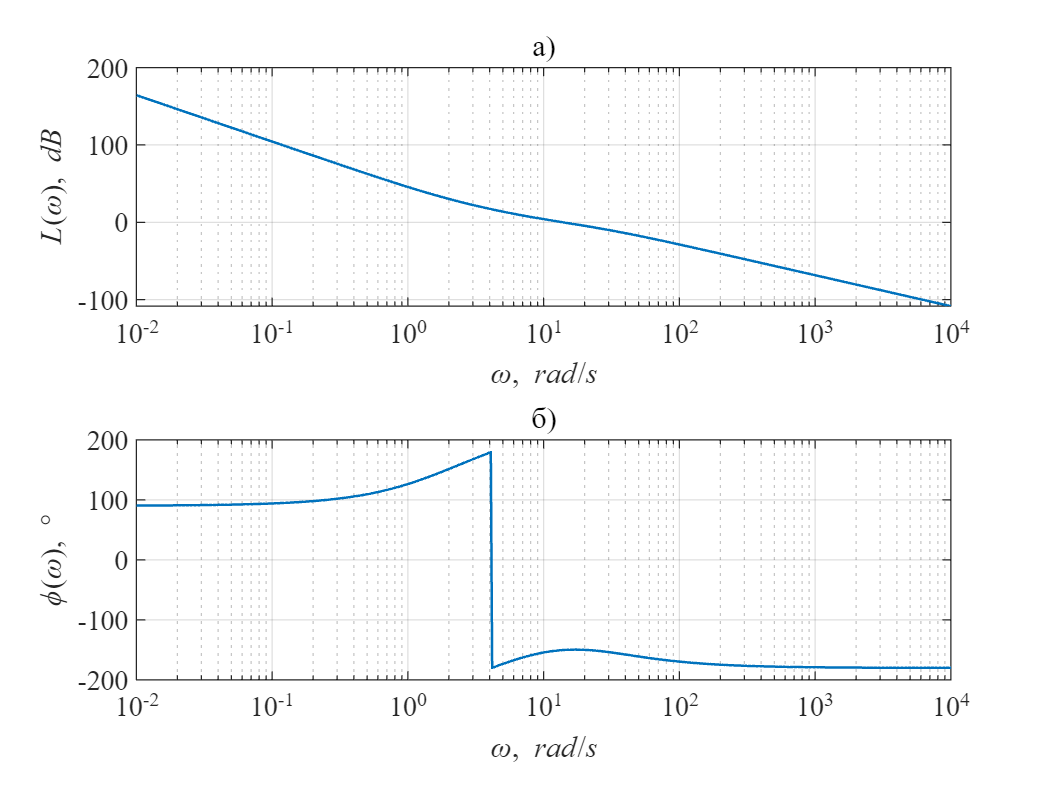

w = 10.^(-2:0.01:4);
sw = 1i*w;

Wol = (16*Tu*sw + 1).*(4*Tu*sw + 1)./(128*Tu^3*sw.^3.*(Tu*sw+1));

[L, phi] = freqplot(w,Wol);

Рисунок 5.4. Графики АЧХ (а) и ФЧХ (б) ПФ разомкнутой системы.

Запас по фазе

[Lmin, ind] = min(abs(L));
phi_marg = phi(ind) - (-180);
fprintf('Запас по фазе: %.3f%c при частоте %.3f рад/c\n',phi_marg,char(176),w(ind))

запас по фазе: 29.8° при частоте 13.8 рад/c


tau_marg = phi_marg*pi/180/w(ind);
fprintf('Критическое запаздывание: %.3f мc\n',tau_marg*1000)

критическое запаздывание: 37.6 мc


[Gm,Pm,Wcg,Wcp] = margin(tf(num,den))

Gm = 0.1455

Pm = 29.7830

Wcg = 4.1539

Wcp = 13.8519

Запас по амплитуде

[L_marg,ind] = max(phi);
amp_marg = 0 + L(ind);
fprintf('Запас по амплитуде: %.1f при частоте %.1f рад/c',amp_marg, w(ind))

Запас по амплитуде: 17.1 при частоте 4.1 рад/c

#### Показатель колебательности

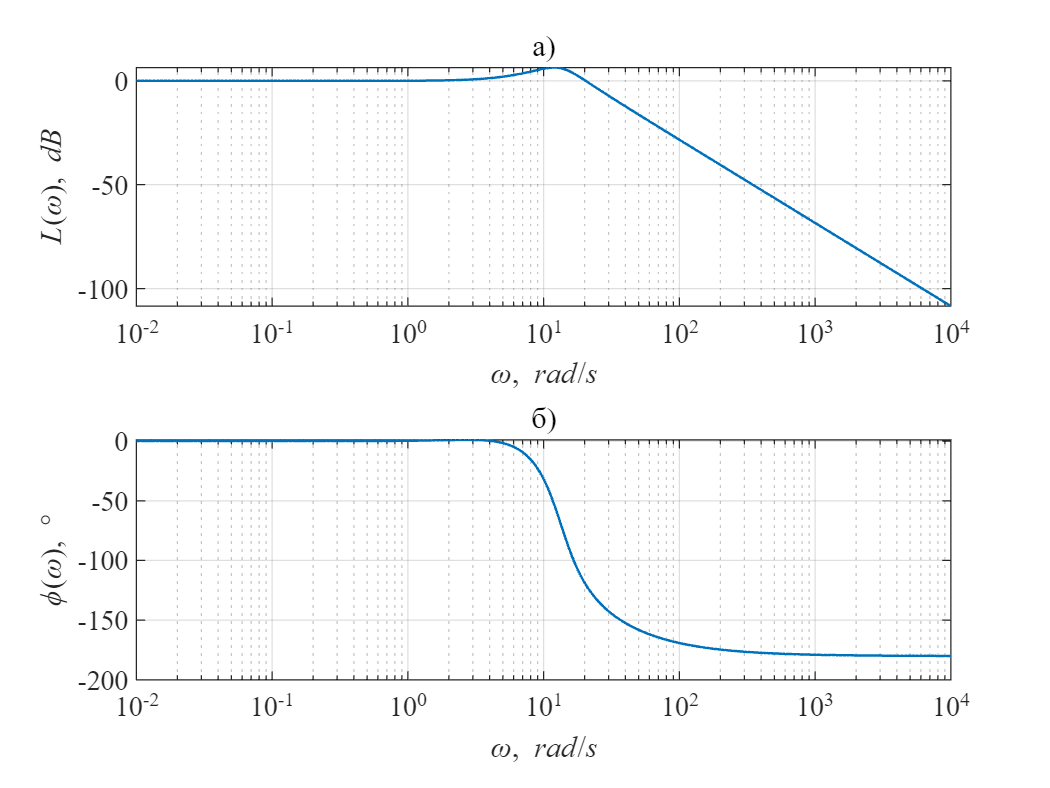

Wcl = Wol./(1 + Wol);

[L,phi] = freqplot(w,Wcl);

Рисунок 5.5. Графики АЧХ (а) и ФЧХ (б) ПФ замкнутой системы.

M = 10^((max(L)-L(1))/20)/10^(L(1)/20);
fprintf('Показатель колебательности M: %.3f \n',M)

Показатель колебательности M: 2.081 
